
start_pos = 0

start_pos = 0

stop_pos = pi

stop_pos = 3.1416

v_max = 10

v_max = 10

a_max = 0.5

a_max = 0.5000

dis = mod(stop_pos - start_pos + 2*pi,2*pi)

dis = 3.1416

inverse = 0;
if mod(start_pos - stop_pos + 2*pi,2*pi) < dis 
    inverse = 1;
    dis = mod(start_pos - stop_pos + 2*pi,2*pi)
end
start_pos = 0;
stop_pos = dis;
ti = 0;

p = [];
if dis < (v_max^2)/a_max
    ta = sqrt(dis/a_max);
    T = 2*ta;
    tf = ti+T;
    for t = 0:0.01:T
        if t <= ti+ta
            p = [p start_pos + 1/2*a_max*(t-ti)^2];
        else
            p = [p stop_pos-1/2*a_max*(tf-t)^2];
        end
    end
else
    T = (dis*a_max + v_max^2)/(a_max*v_max);
    ta = v_max/a_max;
    tf = ti+T;
    for t = 0:0.01:T
        if t <= ti+ta
            p = [p start_pos + 1/2*a_max*(t-ti)^2];
        elseif t < tf-ta
            p = [p start_pos + a_max*ta*(t-ti-ta/2)];
        else
            p = [p stop_pos-1/2*a_max*(tf-t-ti)^2];
        end
    
    end
end

if inverse
    p = p*-1;
end

t = (0:0.01:T)';
T

T = 5.0133

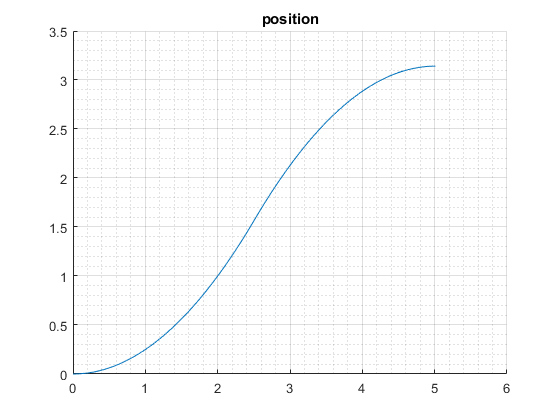

hold on
grid on
grid minor
title('position');
plot(t,p);

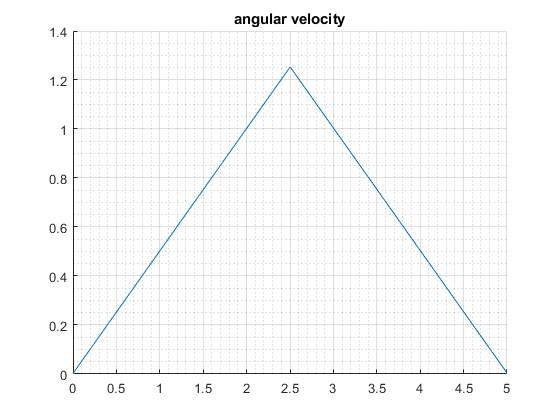


figure
w = diff(p)/0.01;
hold on
grid on
grid minor
title('angular velocity');
plot(t(1:end-1),w);

max_angular_velocity = max(w)

max_angular_velocity = 1.2519

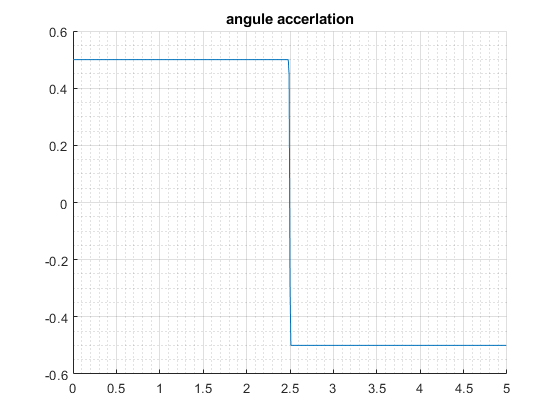


figure
a = diff(w)/0.01;
hold on
grid on
grid minor
title('angule accerlation');
plot(t(1:end-2),a);

max_angular_accerlation = max(a)

max_angular_accerlation = 0.5000